classlist = readtable("C:\Users\GRACE\Desktop\MATLAB\WAR CLASS  LIST FOR MATLAB.xlsx")

classlist = 90×6 table
                NAME                      REG_NO            TRIBEASS       residence     GENDA    AGE
    ____________________________    ___________________    ___________    ___________    _____    ___

    {'AKITENG DEBORAH'         }    {'BU/UP/2025/1531'}    {'TESDA'  }    {'AC'     }    {'F'}    30 
    {'AKWIR MERCY LEAN'        }    {'BU/UP/2025/1532'}    {'NUSA'   }    {'syhaule'}    {'F'}    22 
    {'AUMA PRETTY'             }    {'BU/UP/2025/2109'}    {'NUSA'   }    {'syhaule'}    {'F'}    21 
    {'ELEPOT ERASMUS WANDERA'  }    {'BU/UP/2025/2113'}    {'TESDA'  }    {'syhaule'}    {'M'}    22 
    {'OPUS JONAH'              }    {'BU/UP/2025/2142'}    {'TESDA'  }    {'nyerere'}    {'M'}    20 
    {'KINOBE SOLOMON JAMES'    }    {'BU/UP/2025/3265'}   

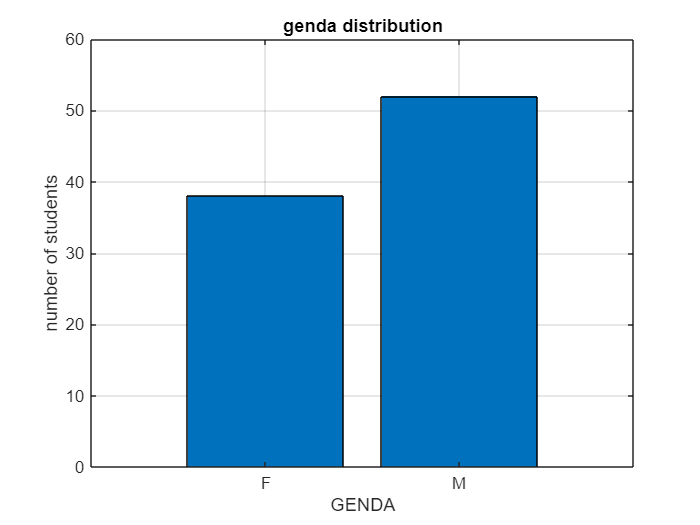

% gender distribution
GENDAcount = groupsummary(classlist,'GENDA');
bar(categorical(GENDAcount.GENDA),GENDAcount.GroupCount);
xlabel('GENDA');
ylabel('number of students');
title('genda distribution');
grid on

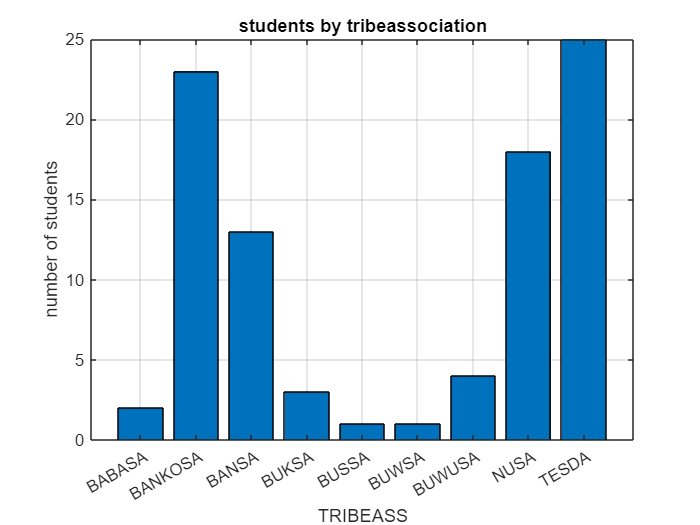

% TRIBEASSOCIIATION
TRIBEcount = groupsummary(classlist,'TRIBEASS');
bar(categorical(TRIBEcount.TRIBEASS),TRIBEcount.GroupCount);
xlabel('TRIBEASS');
ylabel('number of students');
title('students by tribeassociation');
grid on

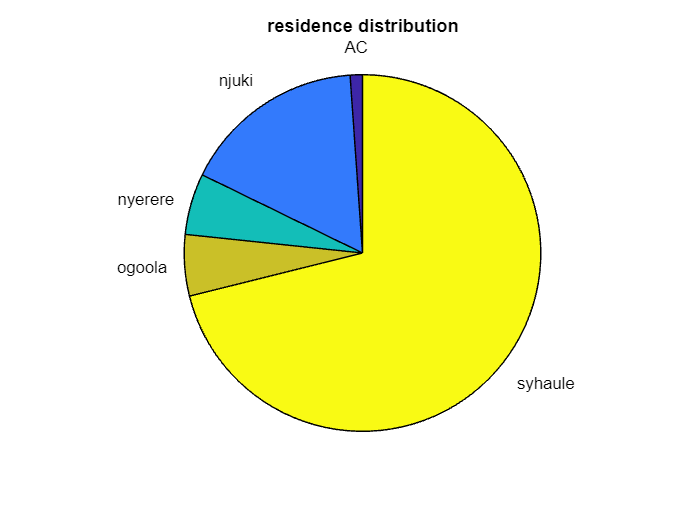

% residence distribution
residencecount = groupsummary(classlist,'residence');
pie(residencecount.GroupCount,residencecount.residence);
title('residence distribution')

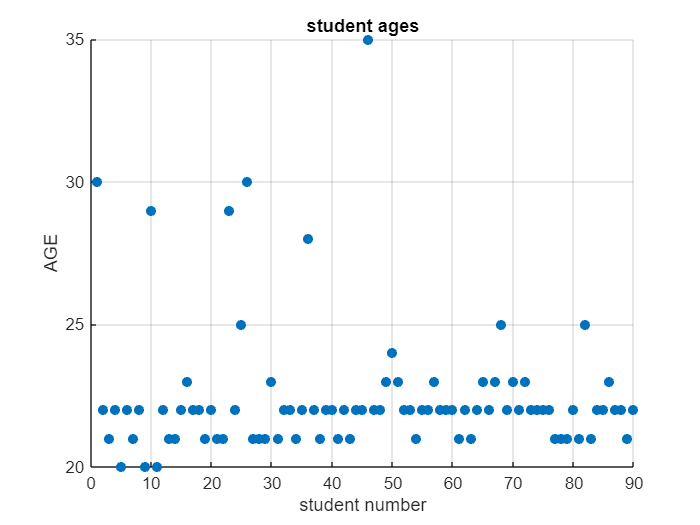

% scatter plot of student number vs age
studentindex = 1:height(classlist);
scatter(studentindex, classlist.AGE,'filled');
xlabel('student number');
ylabel('AGE');
title('student ages');
grid on

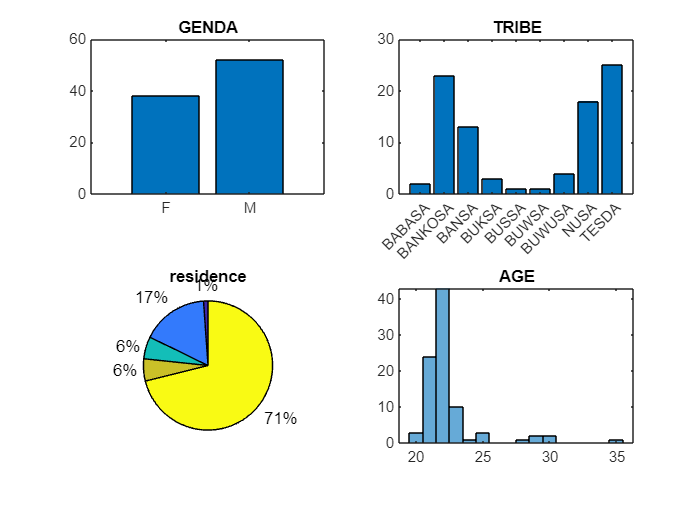


% try and error plot of the combined four plots.
subplot(2,2,1);
GENDAcount = groupsummary(classlist,'GENDA');
bar(categorical(GENDAcount.GENDA),GENDAcount.GroupCount);
title('GENDA');
subplot(2,2,2);
TRIBEcount = groupsummary(classlist,'TRIBEASS');
bar(categorical(TRIBEcount.TRIBEASS),TRIBEcount.GroupCount);
title('TRIBE');
subplot(2,2,3);
residencecount = groupsummary(classlist,'residence');
pie(residencecount.GroupCount);
title('residence');
subplot(2,2,4);
histogram(classlist.AGE);
title('AGE')